% Os dois primeiros exemplos são testes de conceito.

## Conexões não implementadas

Ainda não temos nenhuma conexão diferente de TCP.

Reserva para em caso no futuro seja desejável outras formas de conexão.

E para ajudar a desacoplar e permitir sobrecarga de métodos.

% try     
%     Analysers.Analyser.connGPIB('1234')
% catch exception
%     disp(exception.message)
% end

## Execução com o simulador SA2500PC

Alocação dinâmica ainda não implementada (perfumaria prevista):

Caso só passe o IP, teríamos uma opção de auto discovery:

% % Auto discovery
% try     
%     Analysers.Analyser.connTCP("localhost");
% catch exception
%     disp(exception.message)
% end
% 
% % Ref. portas a varrer:
% % 5025  - Keysight e R&S
% % 5555  - R&S EB500
% % 9001  - Anritsu
% % 34835 - Tektronix 

Instrumento simulado (Download em [SA2500PC](https://anatel365-my.sharepoint.com/:f:/r/personal/eric_anatel_gov_br/Documents/Softwares/Tektronix/SA2500PC?csf=1&web=1&e=Qde3u5)).

Conectado e respondendo à sua identificação:

% disp('Propriedades:')
% callTCP = Analysers.Analyser.connTCP("localhost", 34835) % Simulador
callTCP = Analysers.Analyser.connTCP("192.168.48.2", 34835)

callTCP =   dictionary (string ⟼ string) with 6 entries:

    "Factory" ⟼ "TEKTRONIX"
    "model"   ⟼ "SA2500"
    "serial"  ⟼ "B040211"
    "version" ⟼ "7.050"
    "ip"      ⟼ "192.168.48.2"
    "port"    ⟼ "34835"


## **Instância dinâmica. **

Cada fabricante deve ter, na pasta 'Analysers', sua classe como mesmo nome de sua superclasse (prop:Factory), e cada especifidade de um certo modelo (prop:model) deve estar com o mesmo nome, o que permite escalonar e isolar os componentes em uma interface unificada, e granularizada para o serviço esperado.

O 'Analyser' deve conter todos os comandos genéricos da SCPI (Standard Commands for Programmable Instruments) e IEEE 488.2 Common Commands, este último inicia por um asterisco..

Com base na IDN que o instrumento responde, a instância sempre herda todos os comandos do 'Analyser'.

No caso, o "is a" está representado no classdef como "classdef TEKTRONIX < Analyser", ou seja, Um Tektronix é um analisador, e o SP2500 é um Tektronx ("classdef SA2500PC < TEKTRONIX")

Neste caso herda os comuns e sobrecarrega os comandos do Tektronix, e os específicos do modelo SA2500PC:

disp('Instancia Classes:')

Instancia Classes:


obj = Analysers.Analyser.instance(callTCP);

    "Analyer: Base de comando do fabricante"    "TEKTRONIX"



O simulador fecha quando recebe o comando de reset, então só fingimos o reset para evitar isso (na implementação específica do modelo). O que ainda oportuna outros casos de uso em casos diferentes, como o EB500 que precisa abrir uma porta específica para receber stream UDP.

Um instrumento real não terá o sufixo PC e portanto automaticamente não herdará esse método, o que possibilita compartilar comandos e especificar no modelo o que for diferente nele.

Aplicando uma sobrecarga no modelo SA2500PC com a resposta da classe:

obj.scpiReset;

Analyer.scpiReset: Criando nova conexão TCP.


Comandos gerais de inicialização:

obj.startUp()

TEKTRONIX: Start Ok.


Teste geral de conectividade (SCPI):

obj.ping()

Analyser.ping: Mesma conexão
Analyser.ping: Resposta IDN recebida:
TEKTRONIX,SA2500,B040211,7.050


Obtém parâmetros do objeto: 

disp('getSpan:')

getSpan:


disp(obj.getSpan())

200000000



disp('Parâmetros:')

Parâmetros:


obj.getParms()

ans =   dictionary (string ⟼ string) with 10 entries:

    "Function"  ⟼ "NORM"
    "AVGCount"  ⟼ "20"
    "Detection" ⟼ "POS"
    "UnitPower" ⟼ "DBM"
    "FStart"    ⟼ "759000000"
    "FStop"     ⟼ "959000000"
    "ResAuto"   ⟼ "1"
    "Res"       ⟼ "200000"
    "InputGain" ⟼ "0"
    "Att"       ⟼ "50"


## Operação

Aqui perguntamos se o parâmetro corresponde ao que foi solicitado (assert). E verificamos as respostas no simulador em tempo real:

disp('Pausas para observar o comportamento:')

Pausas para observar o comportamento:



%pause(5) % tempo para ajuste manual de teste.


% % Testes
% obj.setFreq(120000000)
% obj.setSpan(50000)
% assert(str2double(obj.getSpan) == 50000, 'O Span não foi ajustado.')
% obj.setRes(2000)
% assert(str2double(obj.getRes) == 2000, 'O Span não foi ajustado.')
% 
pause(1)
obj.setFreq(100000000)
obj.setSpan(10000)

% disp('Nova conexão simulada pelo ping (caso não responda):')
% obj.conn = [];

% Isso gera um alerta na janela do simulador,
% mas não retorna erro.
% try
%     RBW = obj.getRes();
%     assert(str2double(RBW) == 2000, 'A Resolução foi alterada automaticamente.')
% catch exception
%     disp('Resolução alterada automaticamente para:')
%     disp(RBW)
% end

pause(1)
disp('Amostra em faixa larga')

Amostra em faixa larga


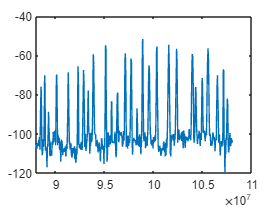

obj.setFreq(88000000, 108000000)
obj.setRes(20000) % Warning: Data out of range

trace = obj.getTrace(1);
plot(trace.freq,trace.value,"DisplayName","value");


% try
%     assert(str2double(obj.getSpan) == 10000, 'O Span não foi ajustado.')
% catch
%     disp('Se atribuir o span depois gera erro "out of range"')
% end

% pause(1)
% % Observar que o com Spectrum o RBW Auto em verde
% obj.setRes('Auto')
% obj.setFreq(88000000, 108000000)

% Para observar a faixa em auto level
pause(2)
% Escolhe uma portadora FM para análise
freq = 100300000;

obj.setSpan(500000)
obj.setFreq(freq)
assert(str2double(obj.getSpan) == 500000, 'O Span não foi ajustado.')

% Cuidado! Os pisos não correspondem aos de um instrumento real!

%obj.preAmp('On')

% % Teste dos níveis de atenuação (comentado para poupar tempo)
% % Para observar abrir o menu Spectrum -> More -> Ampl
% for attstep = 5:5:50
%     obj.setAtt(attstep);
%     pause(0.5)
% 
%     % O pré desativa sozinho com att acima de 15dB
%     % Mesmo expressamente solicitado, sem erro:
%     obj.preAmp('On')
% end


Trace:


       freq        value 
    __________    _______

    1.0005e+08    -124.09
    1.0005e+08    -118.07
    1.0005e+08    -119.72
    1.0005e+08    -124.08
    1.0005e+08    -122.49



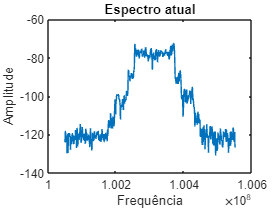


% Esse bloco try é para liberar a conexão em caso de erro.
try
    trace = obj.getTrace(1);

    disp('Trace:')
    
    
    
    % Só as 5 primeiras linhas
    disp(trace (1:5,:));
    
    
    
    % Plota o Trace
    p = plot(trace.freq,trace.value,"DisplayName","value");
    
    % Add xlabel, ylabel, title, and legend
    xlabel("Frequência")
    ylabel("Amplitude")
    title("Espectro atual")
    legend('off');    


    trcs = fcn.getTracesFromUnit(obj, 10);

ans = "Trace 1"

ans = "Trace 2"

ans = "Trace 3"

Analyser: Aguardando sincronismo ...


ans = "Trace 4"

ans = "Trace 5"

Analyser: Aguardando sincronismo ...


ans = "Trace 6"

Analyser: Aguardando sincronismo ...


ans = "Trace 7"

ans = "Trace 8"

ans = "Trace 9"

ans = "Trace 10"


    disp("Total size:")

Total size:


    size(trcs)

ans =     10   501


    disp(trcs)

 -120.7582 -122.7377 -121.2379 -121.9706 -119.6026 -124.6685 -119.5793 -122.0503 -124.1646 -119.9926 -119.3859 -119.5658 -121.7689 -121.6637 -122.5508 -120.3580 -122.3560 -133.2119 -128.4991 -123.5497 -123.8896 -120.9128 -126.8165 -119.2432 -117.2246 -125.1771 -118.3209 -122.4822 -123.2579 -124.3638 -124.3802 -126.4832 -123.5273 -126.9575 -119.6153 -123.7985 -120.4975 -121.6278 -117.3394 -123.8723 -125.9080 -123.1335 -122.8093 -126.8818 -121.4901 -123.9336 -122.5068 -118.3600 -117.8291 -120.5337 -123.3396 -120.7880 -123.0601 -124.4606 -124.9019 -126.5989 -121.5328 -118.4723 -117.9807 -121.9891 -120.9270 -125.8994 -123.4007 -122.2581 -121.4850 -127.0152 -122.2611 -121.2671 -122.2022 -123.8757 -121.1809 -127.9906 -127.4841 -128.6639 -132.6165 -122.6746 -123.9737 -118.9292 -119.3735 -128.9154 -122.0044 -121.8588 -119.2423 -116.4707 -127.9934 -128.2871 -124.2370 -125.4893 -122.0983 -124.0549 -127.7053 -127.4209 -123.2812 -123.0344 -129.2455 -123.4239 -120.8791 -120.6617 -122.8737 -123.8079


    % Um tempo para o analisador respirar
    % Porque eventualmente ele não responde
    pause(0.2)

    freq = 100300200;
    obj.setFreq(freq)
    disp('Leitura do marcador:')

Leitura do marcador:


    nivel = obj.getMarker(freq, 1);
    fprintf('Em %i MHz o nível é: %f\n', freq, nivel);

Em 100300200 MHz o nível é: -72.707726



catch exception
    % Encerra ativamente a conexão
    % Para liberar a porta em caso de erro
    obj.disconnect();
    error('TestTektronix: %s', exception.identifier);
end

% Se tudo der certo, encerra a conexão.
obj.disconnect()


disp("Pronto")

Pronto
